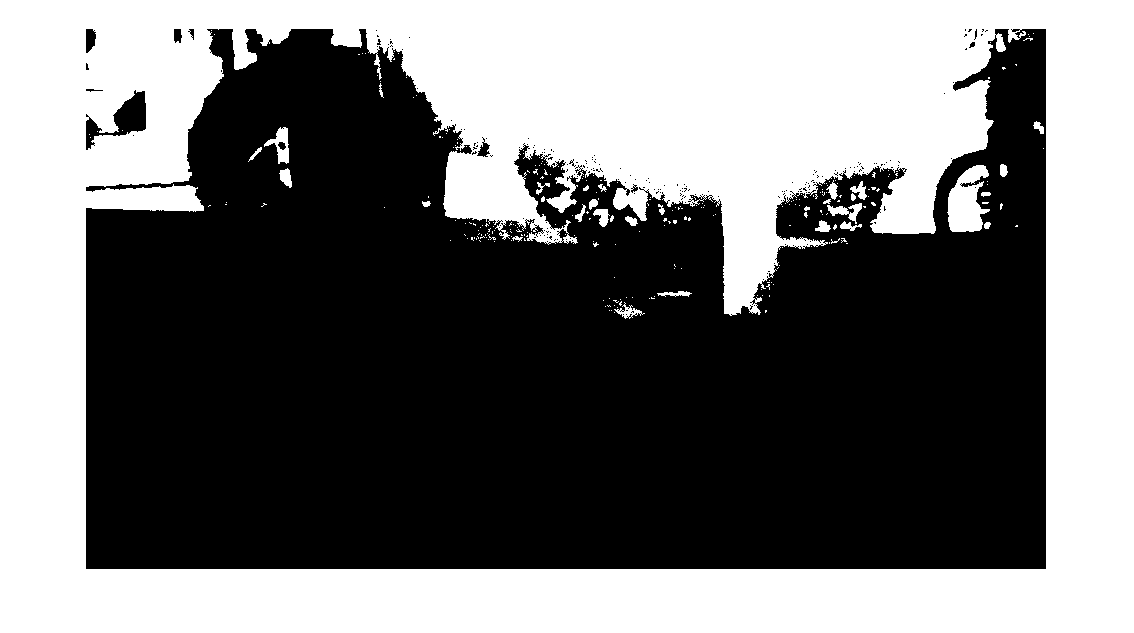

%二值化两幅图像
img1=imread('alpha9.bmp');
img2=imread('alpha25.bmp');
img1=rgb2gray(img1);
img2=rgb2gray(img2);
img1_=imbinarize(img1);
imshow(img1_);

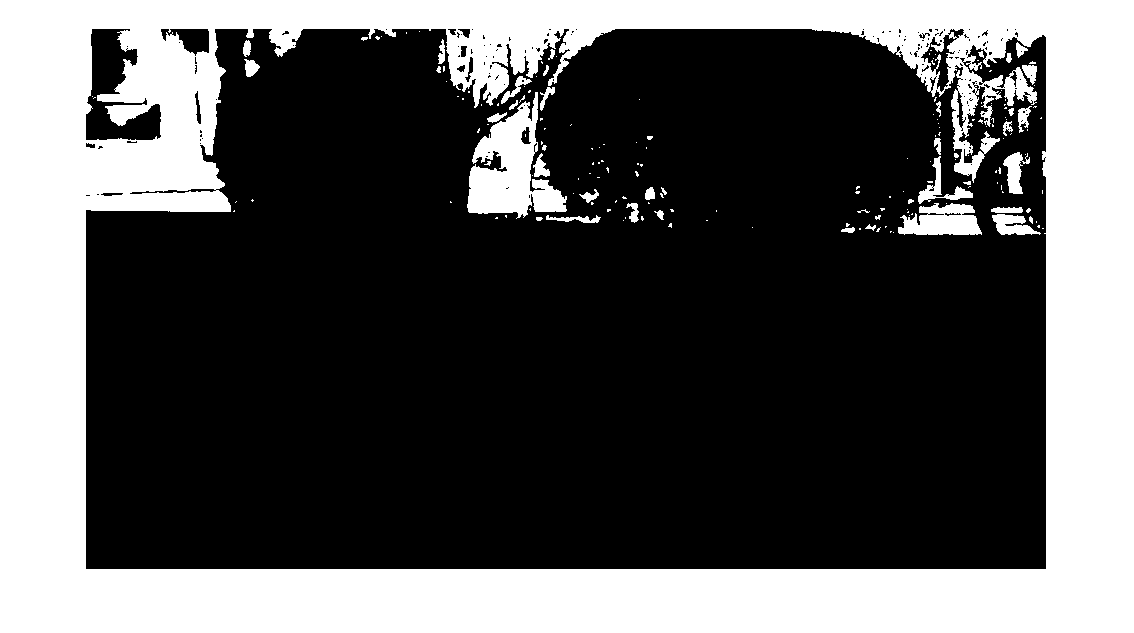

img2_=imbinarize(img2);
imshow(img2_);

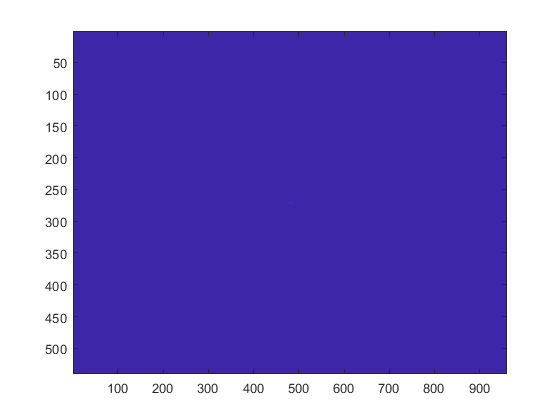

%低通滤波
f1=fft2(img1);
f2=fft2(img2);
f1_shift=fftshift(f1);
imagesc(abs(fftshift(f1)));

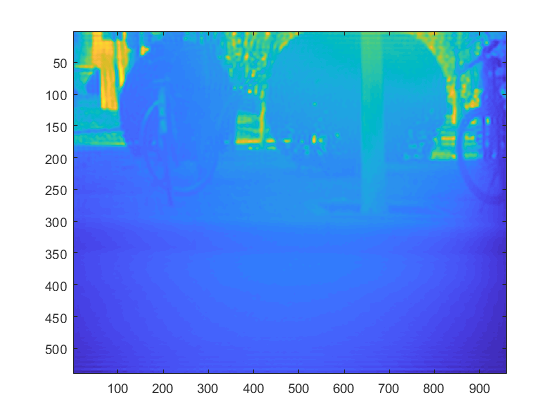

f1_=zeros(540,960);
f1_(200:340,400:560)=f1_shift(200:340,400:560);
img1_=ifft2(ifftshift(f1_));
imagesc(abs(img1_));

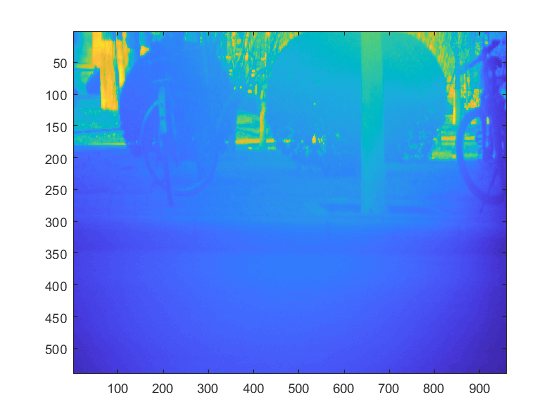

img1__=ifft2(f1);
imagesc(img1__);

% f1_norm=log(abs(f1)+1);
% imagesc(f1_norm);
% f1_norm_=log(abs(fftshift(f1))+1);
% imagesc(f1_norm_);
% f1_(50:490,50:910)=f1_norm_(50:490,50:910);


img1_norm=real(ifft2(ifftshift(f1_)));

img1_norm=im2uint8(mat2gray(img1_norm));
imagesc(img1);

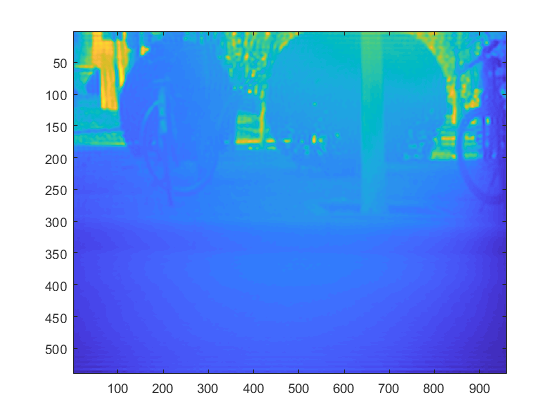

imagesc(img1_norm);